% shouvik96mistry@gmail.com
clear;
close all;

## PN Sequence

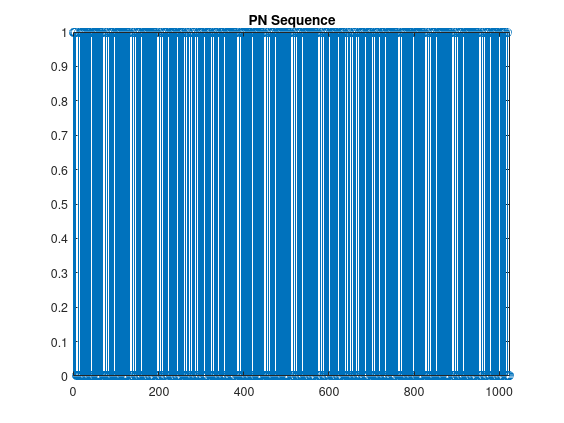

N = 1024;
SIG_AMP = 5;

pn_generator = comm.PNSequence("InitialConditions",[1 1 1 1 1 1], "Polynomial", [1 0 0 0 0 1 1], "SamplesPerFrame", N);
pn_sequence = pn_generator()';

figure(1)
stem(pn_sequence)
title('PN Sequence')
xlim([-1, N+1])

## Modulation

Modulated_Sequence = zeros(2, floor(N/2));

for i=1:2:N
    if (pn_sequence(i) == 0) && (pn_sequence(i + 1) == 0)
        Modulated_Sequence(1, floor((i+1)/2)) = SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = SIG_AMP;
    elseif (pn_sequence(i) == 0) && (pn_sequence(i + 1) == 1)
        Modulated_Sequence(1, floor((i+1)/2)) = SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = -SIG_AMP;
    elseif (pn_sequence(i) == 1) && (pn_sequence(i + 1) == 0)
        Modulated_Sequence(1, floor((i+1)/2)) = -SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = -SIG_AMP;
    else
        Modulated_Sequence(1, floor((i+1)/2)) = -SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = SIG_AMP;
    end  
end

% scatter_plot(Modulated_Sequence);

## Adding Noise and Scatter Plot

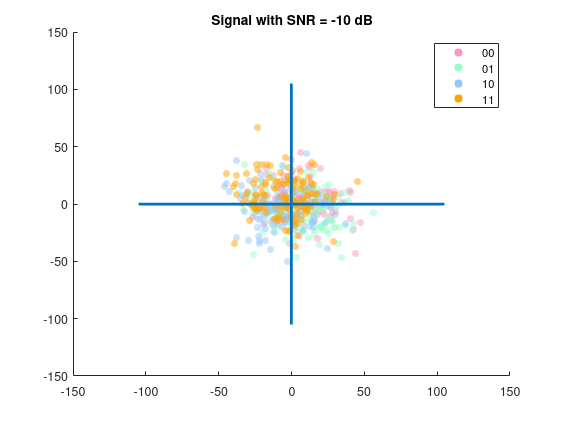

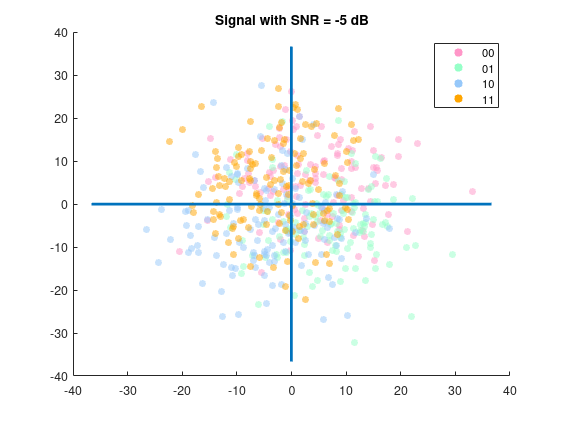

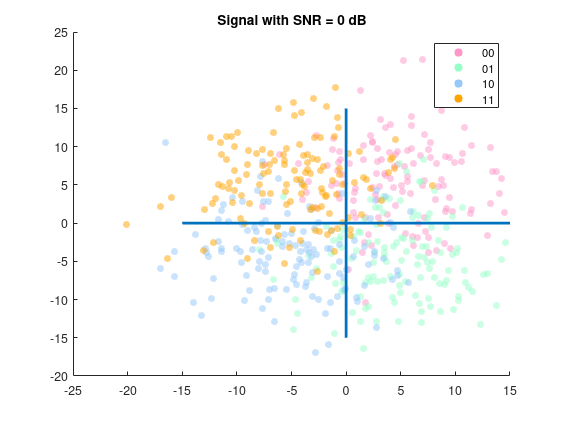

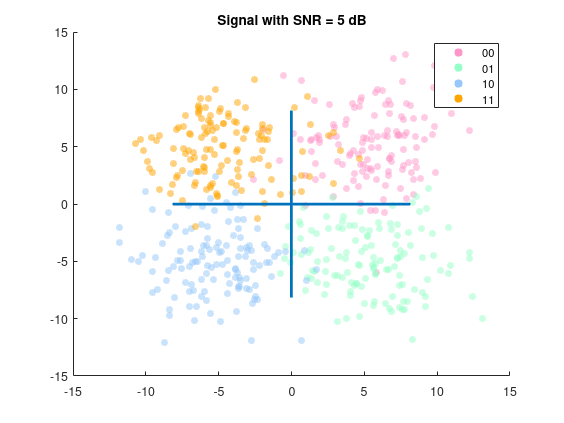

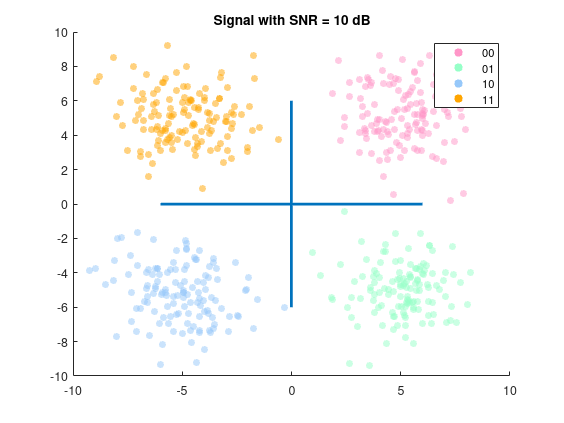

SNRs = [-10, -5, 0, 5, 10];

for i = 1:5
    scatter_plot(Modulated_Sequence, SNRs(i), SIG_AMP, i + 1, sprintf("Signal with SNR = %d dB", SNRs(i)));
end

## Demodulation

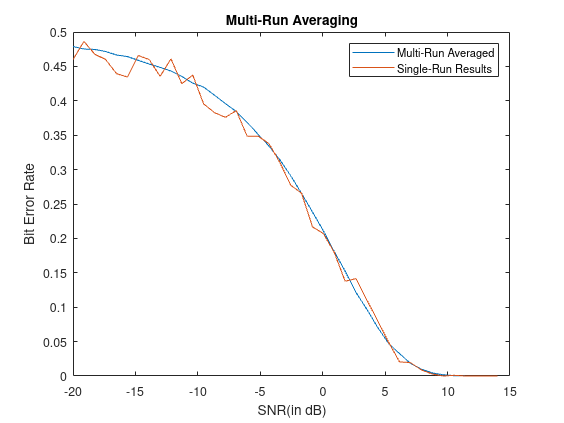

l = length(Modulated_Sequence);

N_points = 40;
N_reps = 256;

SNRs = linspace(-20, 14, N_points);
BERs = zeros(size(SNRs));

single_BERs = zeros(size(SNRs));

for k = 1:N_points
    SNR = SNRs(k);
    BER = 0;
    for j = 1:N_reps
        y_bar = Modulated_Sequence;
        x = SIG_AMP * sqrt(10 .^ (-SNR/10)) * randn(1, length(y_bar));
        y = SIG_AMP * sqrt(10 .^ (-SNR/10)) * randn(1, length(y_bar));
        y_bar(1, :) = y_bar(1, :) + x;
        y_bar(2, :) = y_bar(2, :) + y;

        % y_bar = awgn(Modulated_Sequence, SNR);
        
        Demodulated_Sequence = zeros(1, 2 * l);
        
        for i=1:l
            x = y_bar(1, i);
            y = y_bar(2, i);
        
            if x > 0 && y>0
                Demodulated_Sequence(i * 2 - 1) = 0;
                Demodulated_Sequence(i * 2) = 0;
            elseif x>0 && y<0
                Demodulated_Sequence(i * 2 - 1) = 0;
                Demodulated_Sequence(i * 2) = 1;
            elseif x <0 && y<0
                Demodulated_Sequence(i * 2 - 1) = 1;
                Demodulated_Sequence(i * 2) = 0;
            else
                Demodulated_Sequence(i * 2 - 1) = 1;
                Demodulated_Sequence(i * 2) = 1;
            end
        end
        single_BERs(k) = (1 - sum(pn_sequence == Demodulated_Sequence)/2/l);
        BER = BER + (1 - sum(pn_sequence == Demodulated_Sequence)/2/l);
    end
    BERs(k) = BER / N_reps;
end
Qs = 1 - normcdf(sqrt(0.5 * 10.^(SNRs / 10)));
Analytical = 1.5 * Qs - Qs .^ 2;

figure(9)
plot(SNRs, BERs)
hold on
plot(SNRs, single_BERs)
legend("Multi-Run Averaged", "Single-Run Results")
% semilogy(SNRs, Analytical)
hold off
title("Multi-Run Averaging")
xlabel("SNR(in dB)")
ylabel("Bit Error Rate")

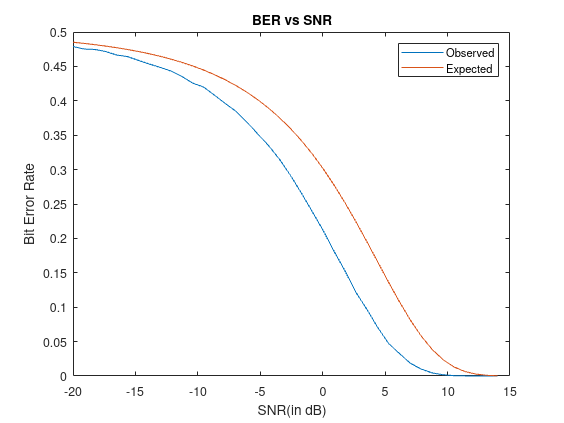


figure(7)
plot(SNRs, BERs)
hold on
plot(SNRs, Analytical)
legend("Observed", "Expected")
% semilogy(SNRs, Analytical)
hold off
title("BER vs SNR")
xlabel("SNR(in dB)")
ylabel("Bit Error Rate")

## Gray Code

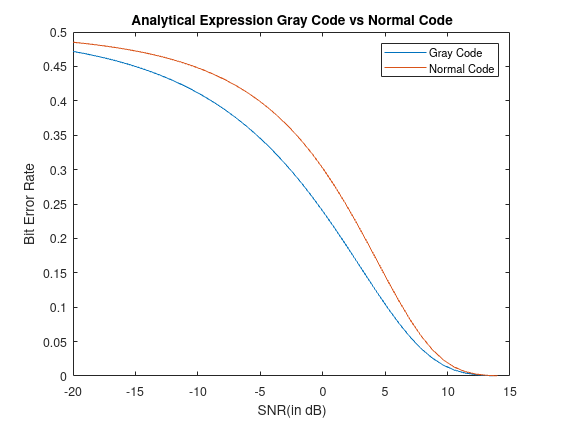

Modulated_Sequence = zeros(2, floor(N/2));

for i=1:2:N
    if (pn_sequence(i) == 0) && (pn_sequence(i + 1) == 0)
        Modulated_Sequence(1, floor((i+1)/2)) = SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = SIG_AMP;
    elseif (pn_sequence(i) == 0) && (pn_sequence(i + 1) == 1)
        Modulated_Sequence(1, floor((i+1)/2)) = SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = -SIG_AMP;
    elseif (pn_sequence(i) == 1) && (pn_sequence(i + 1) == 1)
        Modulated_Sequence(1, floor((i+1)/2)) = -SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = -SIG_AMP;
    else
        Modulated_Sequence(1, floor((i+1)/2)) = -SIG_AMP;
        Modulated_Sequence(2, floor((i+1)/2)) = SIG_AMP;
    end  
end

l = length(Modulated_Sequence);

N_points = 40;
N_reps = 256;

SNRs = linspace(-20, 14, N_points);
BERs_gray = zeros(size(SNRs));

for k = 1:N_points
    SNR = SNRs(k);
    BER = 0;
    for j = 1:256
        y_bar = Modulated_Sequence;
        x = SIG_AMP * sqrt(10 .^ (-SNR/10)) * randn(1, length(y_bar));
        y = SIG_AMP * sqrt(10 .^ (-SNR/10)) * randn(1, length(y_bar));
        y_bar(1, :) = y_bar(1, :) + x;
        y_bar(2, :) = y_bar(2, :) + y;

        % y_bar = awgn(Modulated_Sequence, SNR);
        
        Demodulated_Sequence = zeros(1, 2 * l);
        
        for i=1:l
            x = y_bar(1, i);
            y = y_bar(2, i);
        
            if x > 0 && y>0
                Demodulated_Sequence(i * 2 - 1) = 0;
                Demodulated_Sequence(i * 2) = 0;
            elseif x>0 && y<0
                Demodulated_Sequence(i * 2 - 1) = 0;
                Demodulated_Sequence(i * 2) = 1;
            elseif x <0 && y<0
                Demodulated_Sequence(i * 2 - 1) = 1;
                Demodulated_Sequence(i * 2) = 1;
            else
                Demodulated_Sequence(i * 2 - 1) = 1;
                Demodulated_Sequence(i * 2) = 0;
            end
        end
        
        BER = BER + (1 - sum(pn_sequence == Demodulated_Sequence)/2/l);
    end
    BERs_gray(k) = BER / N_reps;
end
Qs = 1 - normcdf(sqrt(0.5 * 10.^(SNRs / 10)));
Analytical = Qs;

figure(10)
plot(SNRs, Analytical)
hold on
plot(SNRs, 1.5 * Analytical - Analytical .^ 2)
hold off
legend("Gray Code", "Normal Code")
title("Analytical Expression Gray Code vs Normal Code")
xlabel("SNR(in dB)")
ylabel("Bit Error Rate")

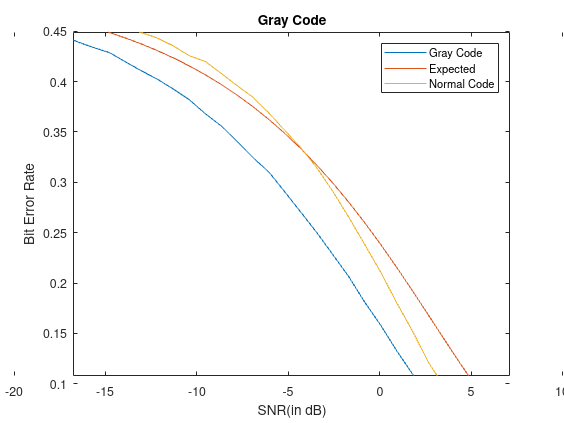


figure(8)
plot(SNRs, BERs_gray)
hold on
plot(SNRs, Analytical)
plot(SNRs, BERs)
legend("Gray Code", "Expected", "Normal Code")
% semilogy(SNRs, Analytical)
hold off
title("Gray Code")
xlabel("SNR(in dB)")
ylabel("Bit Error Rate")

## Functions

function scatter_plot(data, snr, SIG_AMP, num, name)
    [r, c] = size(data);
    
    Q1 = [];
    Q2 = [];
    Q3 = [];
    Q4 = [];
    
    for i=1:c
        x = data(1, i);
        y = data(2, i);
    
        if (x>0) && (y > 0)
            Q1(length(Q1) + 1, :) = [x, y];
        elseif (x>0) && (y < 0)
            Q2(length(Q2) + 1, :) = [x, y];
        elseif (x<0) && (y < 0)
            Q3(length(Q3) + 1, :) = [x, y];
        elseif (x<0) && (y > 0)
            Q4(length(Q4) + 1, :) = [x, y];
        end
    end
    
    figure(num)
    hold on
    if ~isempty(Q1)
        Q1(2, :) = [];
        x = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q1), 1);
        y = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q1), 1);
        Q1(:, 1) = Q1(:, 1) + x;
        Q1(:, 2) = Q1(:, 2) + y;
        scatter(Q1(:, 1), Q1(:, 2), 25, [255/255 150/255 200/255], 'filled', 'AlphaData', 1 * ones(1, length(Q1)), "MarkerFaceAlpha", "flat")
    end
    if ~isempty(Q2)
        Q2(2, :) = [];
        x = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q2), 1);
        y = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q2), 1);
        Q2(:, 1) = Q2(:, 1) + x;
        Q2(:, 2) = Q2(:, 2) + y;
        scatter(Q2(:, 1), Q2(:, 2), 25, [150/255 255/255 200/255], 'filled', 'AlphaData', 1 * ones(1, length(Q2)), "MarkerFaceAlpha", "flat")
    end
    if ~isempty(Q3)
        Q3(2, :) = [];
        x = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q3), 1);
        y = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q3), 1);
        Q3(:, 1) = Q3(:, 1) + x;
        Q3(:, 2) = Q3(:, 2) + y;
        scatter(Q3(:, 1), Q3(:, 2), 25, [150/255 200/255 250/255], 'filled', 'AlphaData', 1 * ones(1, length(Q3)), "MarkerFaceAlpha", "flat")
    end
    if ~isempty(Q4)
        Q4(2, :) = [];
        x = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q4), 1);
        y = SIG_AMP * sqrt(10 .^ (-snr/10)) * randn(length(Q4), 1);
        Q4(:, 1) = Q4(:, 1) + x;
        Q4(:, 2) = Q4(:, 2) + y;
        scatter(Q4(:, 1), Q4(:, 2), 25, [255/255 165/255   0], 'filled', 'AlphaData', 1 * ones(1, length(Q4)), "MarkerFaceAlpha", "flat")
    end
    SNR_lin = 1 + 2 * 10.^(-snr/10);
    line([-SNR_lin*SIG_AMP SNR_lin*SIG_AMP], [0 0], 'linewidth', 2)
    line([0 0], [-SNR_lin*SIG_AMP SNR_lin*SIG_AMP], 'linewidth', 2)
    hold off
    legend("00", "01", "10", "11")
    title(name)
end
